clc; clear all; close all;

#### Establish Parameters

% PARAMETERS FOR tx_utsav.dat and rx_utsav.dat
% Tx/Rx Data Rate is 2e6, i.e. 2 Mbps
% Gain is set to 60, Frequency is 4000 GHz 

% PARAMETERS FOR tx2_utsav.dat and rx2_utsav.dat
% Tx/Rx Data Rate is 4e6, i.e. 4 Mbps
% Gain is set to 60, Frequency is 4000 GHz 

% PARAMETERS FOR tx3_utsav.dat and rx3_utsav.dat
% Tx/Rx Data Rate is 6e6, i.e. 6 Mbps
% Gain is set to 60, Frequency is 4000 GHz  

N_Training = 16;                % Sets of Training Data 
N_XData = 84;                   % Sets of True Data 
Bits_per_set = 48;              % Bits per set of data
n_data = N_XData+N_Training;
Bits_per_block_Guard = 64;      % Bits per block with guard data and pilot signals
size_training_data = Bits_per_set*N_Training;       % Size of Training Data - 16 sets of 48 bits: 768 bits
size_X = Bits_per_set*N_XData;                      % Size of data - 84 sets of 48 bits: 4032 bits
Size_PC = 16;                   % Size of Cyclic Prefix

### Read Files and Load Data

% Load OFDM preamble
load("variables.mat", "preamble", "message", "Prep_data");

% Open the file containing the received samples
f2 = fopen('rx_utsav.dat', 'rb');

% read data from the file
tmp = fread(f2, 'float32');

% close the file
fclose(f2);

% Create a complex vector
y_before_trim = tmp(1:2:end)+1i*tmp(2:2:end);

figure(1)
stem(y_before_trim)

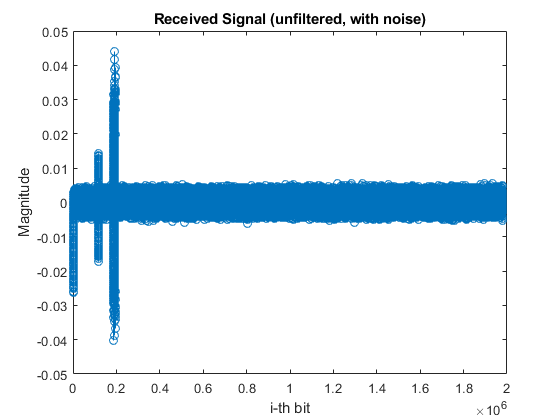

title("Received Signal (unfiltered, with noise)")
xlabel("i-th bit")
ylabel("Magnitude")


% .\rx_samples_to_file ‐‐freq 4000e6 ‐‐rate 6e6 ‐‐type float ‐‐args "serial=30CD3E8" ‐‐ant "TX/RX" ‐‐subdev "A:A" ‐‐gain 60 ‐‐file rx2_utsav.dat
% .\tx_samples_from_file ‐‐freq 4000e6 ‐‐rate 6e6 ‐‐type float ‐‐args "serial=30CD3E1" ‐‐ant "TX/RX" ‐‐subdev "A:A" ‐‐gain 60 ‐‐file tx2_utsav.dat

[y1x1,lag1] = xcorr(y_before_trim,preamble);
[~, Index] = max(abs(y1x1));
shift = lag1(Index)

shift = 187364

% Assume length of data transmitted is known
tx_len = 8192;

% Trim data from xcorr'd lags  ($shift) to length of tx ($tx_len)
rx_trim = y_before_trim(shift:shift+tx_len-1);    % Should be 8192 bits in size

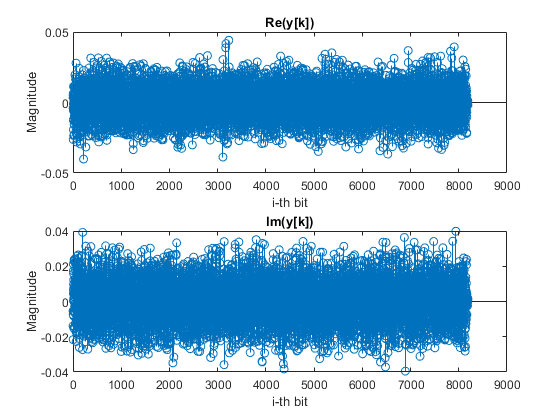

y_real = real(rx_trim);
y_imag = imag(rx_trim);

figure(2);
subplot(2, 1, 1);
stem(y_real);
title("Re(y[k])");
xlabel("i-th bit");
ylabel("Magnitude");
subplot(2, 1, 2);
stem(y_imag);
title("Im(y[k])");
xlabel("i-th bit");
ylabel("Magnitude");

### Schmidl-Cox Algorithm 

len_lts = 64;           % length of 1 lts sample
headers = len_lts*3;    % 3 lts samples total
lts_rx = rx_trim(headers+1:end);

% Frequency Offset Estimation
f_sum = 0;
for i = 1:1:64      % Number of subcarriers  
    f_sum = f_sum + angle(lts_rx(96+i)/lts_rx(32+i));
end
f_delta = (f_sum)/(64*64); % average out 64 values and remove 64 from exponential

% Frequency Offset Correction
rx_freq_corr = zeros(length(rx_trim)-headers,1);
for j=1:1:length(rx_trim(headers+1:end))
    rx_freq_corr(j) = rx_trim(headers+j) * exp(-1i*f_delta*(headers+j));
end

### Channel Estimation

% Obtain Training Data
Size_Training_PC = Size_PC * N_Training + N_Training * Bits_per_set;    % 1024
num_data_w_pilot = 52;
Data_w_Pilots = zeros(num_data_w_pilot*n_data,1); % Data with pilot tones
Prep_w_Pilots = zeros(num_data_w_pilot*n_data,1); % Prep_data with pilot tones (from Tx)

% Removing cyclic prefix from all data
for V = 1:1:n_data
    Set = rx_freq_corr(1 + 80*(V-1):80*V);  % Extract n_data set of 80 bits - 80 bits
    Prep_Set = Prep_data(1 + 64*(V-1):64*V);
    
    remove_prefix = Set(17:end);            % Remove Cyclic prefix and produce true data - 64 bits
    
    dat = fftshift(fft(remove_prefix)); % Move data to the frequency domain
    dat_no_guard_left = dat(7:32);
    dat_no_guard_right = dat(34:59);
    interim_data = [dat_no_guard_left;dat_no_guard_right];
    
    % Prep_data is already in frequency domain
    prep_no_guard_left = Prep_Set(7:32);
    prep_no_guard_right = Prep_Set(34:59);
    interim_prep_data = [prep_no_guard_left;prep_no_guard_right];
    
    Data_w_Pilots(1+num_data_w_pilot*(V-1):num_data_w_pilot*V) = interim_data;
    Prep_w_Pilots(1+num_data_w_pilot*(V-1):num_data_w_pilot*V) = interim_prep_data;
end

Cleaned_Training_Data= Data_w_Pilots(1:Size_Training_PC);


H_est = zeros(num_data_w_pilot,1);              % Create empty vector for Channel Estimate
Original_Training = Prep_w_Pilots(1:N_Training*num_data_w_pilot);            % Obtain original training data
Pre_H_est = zeros(N_Training*num_data_w_pilot,1);


  
% Calculating Channel Estimate for every point 
for Z = 1:1:N_Training*num_data_w_pilot
    Pre_H_est(Z) = Cleaned_Training_Data(Z) / Original_Training(Z);
end

for G = 1:1:num_data_w_pilot
    % Channel_estimate = Cleaned_Training_Data ./ Original_Training; % Estimate the channel
    h_est_obtain = Pre_H_est(G:num_data_w_pilot:624); %64 subcarriers across 12 symbols
    H_est(G) = mean(h_est_obtain);
end
Alpha = Cleaned_Training_Data(1:num_data_w_pilot);
result = Alpha./H_est

result =   -1.0409 - 0.0087i
   0.9547 + 0.0866i
  -0.9613 + 0.0152i
  -0.9924 + 0.0728i
   1.0374 - 0.0904i
  -0.8974 + 0.0485i
   0.9566 - 0.0516i
   1.0201 + 0.1347i
   1.0155 + 0.0721i
   1.0032 + 0.0316i


figure(4);
hold on
stem(result);

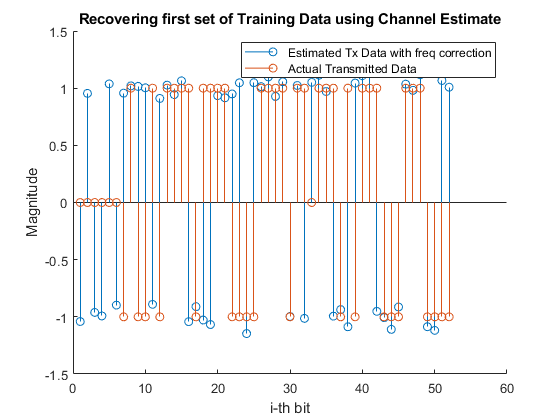

title('Recovering first set of Training Data using Channel Estimate');
stem(Prep_data(1:num_data_w_pilot));
xlabel("i-th bit");
ylabel("Magnitude");
legend("Estimated Tx Data with freq correction", "Actual Transmitted Data")
hold off

#### Decode

% Received data with frequency correction and channel estimation
Y_Freq_corr = zeros(length(Data_w_Pilots),1);

for V = 1:1:n_data
    Y = Data_w_Pilots(1 + num_data_w_pilot*(V-1):num_data_w_pilot*V);   % Extract n_data set of 80 bits - 80 bits
    X_est= Y./H_est;                        % Estimate Tx_data = Rx_data / Channel_Estimate
    Y_Freq_corr(1 + num_data_w_pilot*(V-1):num_data_w_pilot*V) = X_est;
end

### Tx estimate with frequency correction

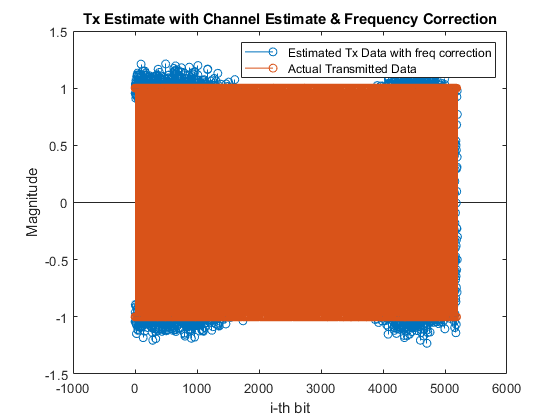

% Normalize frequency corrected, channel estimated data to 
% derive an estimate for Tx_data (without phase correction)
X_est_no_phase = real(Y_Freq_corr) ./ (real(Y_Freq_corr));

figure;
stem(real(Y_Freq_corr));
hold on
stem(real(Prep_w_Pilots));
title('Tx Estimate with Channel Estimate & Frequency Correction');
xlabel("i-th bit");
ylabel("Magnitude");
xlim([-1000,6000]);
ylim([-1.5,1.5]);
legend("Estimated Tx Data with freq correction", "Actual Transmitted Data")
hold off

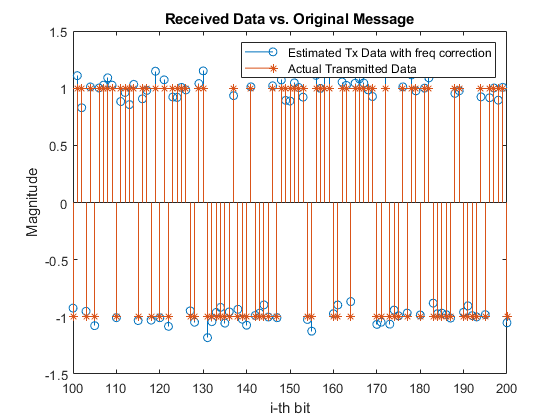


figure;
stem(real(Y_Freq_corr));
hold on
stem(real(Prep_w_Pilots),'*');
title('Received Data vs. Original Message');
xlabel("i-th bit");
ylabel("Magnitude");
xlim([100,200])
ylim([-1.5,1.5])
legend("Estimated Tx Data with freq correction", "Actual Transmitted Data")
hold off

### Phase Correction using Pilot subcarriers

% Phase Offset Estimation
% -21 --> 13 --> 7, -7 --> 26 --> 20, 7 --> 40 --> 33, 21 --> 53 --> 46

X_est_mat = reshape(Y_Freq_corr, num_data_w_pilot, n_data);
Prep_mat = reshape(Prep_w_Pilots, num_data_w_pilot, n_data);
phase_corr = zeros(1,100);
Phase_est = zeros(num_data_w_pilot, n_data);

for k = 1:1:n_data     % Number of symbols
    phase_corr(k) = 0.25*(angle(X_est_mat(7,k) / Prep_mat(7,k)) + angle(X_est_mat(20,k) / Prep_mat(20,k)) ...
                    + angle(X_est_mat(33,k) / Prep_mat(33,k)) + angle(X_est_mat(46,k) / Prep_mat(46,k)));
    Phase_est(:,k) = X_est_mat(:,k) * exp(-1i*phase_corr(k));
end
Recovered_signal = reshape(Phase_est, num_data_w_pilot*n_data, 1);

figure;
hold on
stem(Recovered_signal)

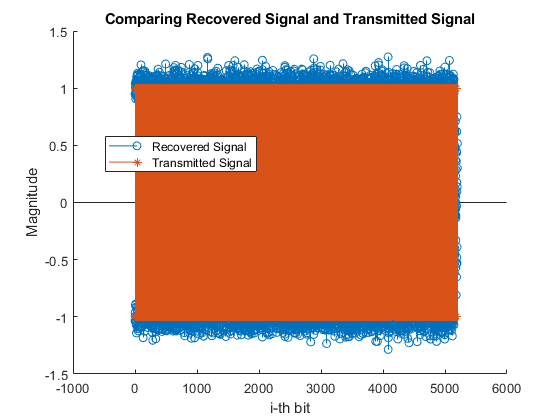


stem(Prep_w_Pilots, '*')
hold off
title("Comparing Recovered Signal and Transmitted Signal")
xlabel("i-th bit");
ylabel("Magnitude");
xlim([-1000,6000]);
ylim([-1.5,1.5]);
legend("Recovered Signal", "Transmitted Signal", 'Location',"best")

### Transmitted Vs Received Data

% Calculating Error
diff = (real(Prep_w_Pilots) - real(Recovered_signal))./((2*real(Prep_w_Pilots)));
Error = abs(sum(diff)/(length(diff))) * 100

Error = 1.9335

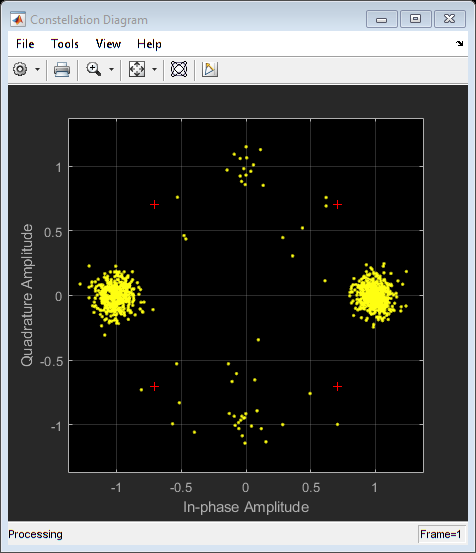

sps = 2;
constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',sps, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',1024);
constDiagram(Recovered_signal)